# Coupled Attitude and Orbit Motion to generate training data

## note

吉村先生からもらったコードで出力方法を変えたやつ．（状態空間を網羅するために）

## references 

## revisions

©2022  y.yoshimura, y.yoshimula@gmail.com, y.yoshimura.a64@m.kyushu-u.ac.jp

clc
clear
close all

% add path for functions
addpath('../yoshimuLibrary-main/attitude');
addpath('../yoshimuLibrary-main/conversion');
addpath('../yoshimuLibrary-main/environment');
addpath('../yoshimuLibrary-main/lightcurves/');
addpath('../yoshimuLibrary-main/object/');
addpath('../yoshimuLibrary-main/orbit/');
addpath('../yoshimuLibrary-main/sphericalGaussian/');
addpath('../yoshimuLibrary-main/srp/');
addpath('../yoshimuLibrary-main/time/');
addpath('../yoshimuLibrary-main/ukf/');
addpath('../yoshimuLibrary-main/utility/');
addpath('../yoshimuLibrary-main/vectorMatrix/');
addpath('../WOBJ_toolbox_Version2b/');
addpath('../../hara_functions/');

## flags and constants

TLE = 1;
model = 2;
% N = 5; % # of training data
lcModel = 'AS';

const = orbitConst;
earthVSOP = vsopConst;

## satellite parameter

if model == 1
    objName = 'flatPlate.obj';
    nCompo = 1; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivitiy
elseif model == 2
    objName = 'boxWing.obj';
    nCompo = 3; % # of object in .obj file
%     nCompo = 2; % boxとwing1つにできる
    sat = readSC(objName, nCompo); % satellite shape and optical parameters
    if nCompo == 3
        sat.J = diag([55, 40, 65]); % moment of inertia, kgm^2
        sat.m = 100; % mass, kg
    elseif nCompo == 2
        sat.J = diag([40, 35, 50]);
        sat.m = 80;
    end
    %   optical parameters at wing (manually...)
    sat.Ca(193:end,:) = 0.1;
    sat.Cd(193:end,:) = 0.6;
    sat.Cs(193:end,:) = 0.3;
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivitiy
else
    error('invalid model flag');
end

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


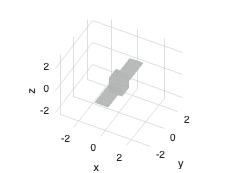

showSC(sat,"Normal","on") % visualize satellite

## Iteration

wStd = 0.1; % standard deviation, deg/s

qdegStep = 30; % 全球方向に振る角度
wdegStep = 45;
% クォータニオンを全球方向に振って初期角度作成
qIniData = qCover(qdegStep, qdegStep);
% ノルム固定して角運動量ベクトルを球面全体に振って初期角速度作成
wIniData = wCover(sat.J, 1, wdegStep);
% それぞれのクォータニオンに全球方向の角運動量ベクトルを付与
[qIniData, wIniData] = qwCover(qIniData, wIniData);


% test用で，(-1, 1)一様分布からランダムな初期角速度を作成
% wInitest = wRand(sat.J, 1, 3);

% wIniData = [wIniData; wInitest]; % テスト用の初期角速度を結合

N = size(wIniData, 1);
for i = 1:N

ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans =      1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


ans = 1×2
     1    69


### initial condition

### attitude

    wIni = wIniData(i,:);
    qIni = qIniData(i,:);

### orbit

tle.oe = $a {\rm [km]}, e,i {\rm [rad]},\Omega {\rm [rad]},\omega{\rm [rad]},M{\rm [rad]}$

    if TLE == 1
        tle = readTLE('JCSAT2.txt', const);
    else
        a = 42164.91220781728; % km
        e = 0.000215800000000; % eccentricity
        inc = 0.000938987137573; % rad
        W = 4.918899828139163; % rad
        w = 0.876621287411436; % rad
        m = 1.585708419923936; % rad

        tle.oe = [a e inc W w m];
        tle.jd = 2.458535992836310e+06;
    end

    [rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
    rIni = rIni .* 10^3; % m
    vIni = vIni .* 10^3; % m/s
    jd = tle.jd; % Julian day, day

    % initial condition
    xIni = [rIni, vIni, qIni, wIni];
%     tspan = 0:5:60*60*6;
%     tspan = 0:3:60*60;
    tspan = 0:3:6;
%     tspan = [0 3];

## observer location

    obsLon = deg2rad(130.216544); % longitude, rad
    obsLat = deg2rad(33.594649); % latitude, rad
    [obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % observer position@ECEF, km
    obsPosECEF = obsPosECEF .* 10^3; % 1x3 vec, m

    qECI2ECEF = earthFullRotQ(const.J2000, tle.jd, 4, const); % (Earth attitude) quaternion from ECI to ECEF
    obsECI = qRotation(4, obsPosECEF, qInv(4, qECI2ECEF)); % observer @ECI, m, 1x3 vec.


## ODE

    options = odeset('RelTol',1e-10,'AbsTol',1e-10);
    [t_, x_] = ode89(@(t,x)eomCowellQ(t,x,const,earthVSOP,sat,jd), tspan, xIni, options);

## data handling

    jdHistory = tle.jd + s2day(t_); % time history in Julian day
    r = x_(:,1:3); % m, position at i-frame
    v = x_(:,4:6); % m/s, velocity at i-frame
    q = x_(:,7:10); % quaternion w.r.t. inertial frame
    w = x_(:,11:13); % rad/s, angular rate  w.r.t. inertial frame

### Sun position and Observer positions

    [lonSun, latSun, rSun] = sun(jdHistory, const, earthVSOP);
    [sunPosI(:,1), sunPosI(:,2), sunPosI(:,3)] = sph2cart(lonSun, latSun, au2km(rSun,const)); % km
    sunPosI = sunPosI .* 10^3; % m
    sunRel = sunPosI - r; % relative vec from sat to sun @inertial frame, nx3, m
    sunPosB = qRotation(4, normRow(sunRel), q);% sun unit directional vectors @body-fixed frame, nx3

    qECI2ECEF = earthFullRotQ(const.J2000, jdHistory, 4, const);
    obsECI = qRotation(4, kron(ones(length(jdHistory),1),obsPosECEF), qInv(4, qECI2ECEF)); % observer position @ECI, nx3 m
    obsRel = obsECI - r; % relative vec from sat to observer @inertial frame, nx3, m
    obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors@inertial frame, nx3,


### Light curve

    nu = shadow(r./10^3, sunPosI./10^3, const); % calc Earth's shadow
    [mApp, ~] = lc(sat, 4, q, r, obsECI, sunPosI, nu, lcModel); % relative magnitude
    fObs = magInv(mApp, vecnorm(obsRel,2,2));

## define training data

    %% define training data
    zyx = q2zyx(4, q);
%     X = [q w];
    X = [q w];
    Y = [t_, mApp];
    
% hara chan----------------------------------------------    
%     % 学習モデルの出力Δx_kを作成，追加 (差を取るため，1行小さくなることに注意)
%     deltaX = zeros(length(X)-1, length(X(1,:)));
%     deltamApp = zeros(length(Y)-1, 1);
% 
%     addpath('hara_functions/'); % yoshimulibraryのqProMat.mlxの使い方がわからなかったから，とりあえず自前のq_pro.mを使う．
% 
%     for j = 1:1:(length(X)-1)
%         % クォータニオンの差分 using Error Quaternions
%         deltaq = q_error(X(j+1,1:4)', X(j,1:4)'); % 転置して列ベクトルにしてる
%         deltaX(j, 1:4) = deltaq'; % 転置して行ベクトルに戻してる
%         % 角速度の差分
%         deltaX(j,5:7) = X(j+1,5:7) - X(j,5:7);
% 
%         % Light Curvesの差分を追加
%         deltamApp(j,1) = Y(j+1,2) - Y(j,2); 
%     end
%     X = [X(1:length(deltaX), :), deltaX];
%     Y = [Y(1:length(deltamApp), :), deltamApp];
% -----------------------------------------------------------------
% データを保存する
    curdir = pwd;
    savedir = strcat(curdir, '/../../gpr/train_data_using_yoshimulibrary');
    if model == 1
        fName = strcat(savedir, '/X_flatPlate', sprintf('%05d', i), '.csv');
        writematrix(X, fName);
        fName = strcat(savedir, '/t_mApp_flatPlate', sprintf('%05d', i), '.csv');
        writematrix(Y, fName);
    elseif model == 2
        if nCompo == 3
            fName = strcat(savedir, '/X_boxWing', sprintf('%05d', i), '.csv');
            writematrix(X, fName);
            fName = strcat(savedir, '/t_mApp_boxWing', sprintf('%05d', i), '.csv');
            writematrix(Y, fName);
        elseif nCompo == 2
            fName = strcat(savedir, '/X_boxOneWing', sprintf('%05d', i), '.csv');
            writematrix(X, fName);
            fName = strcat(savedir, '/t_mApp_boxOneWing', sprintf('%05d', i), '.csv');
            writematrix(Y, fName);
        end
%     else
%         error('invalid model flag'); % 上で既にやってるからいらなさそう
    end

end

## show figs

% figure
% plot3(r(:,1)./1000, r(:,2)./1000,r(:,3)./1000)
% hold on
% plot3(obsECI(:,1)./1000, obsECI(:,2)./1000,obsECI(:,3)./1000,'r')
% tmp = jd2GMST(jdHistory(end));
% drawEarth(tmp, 0.6, const);
% xlabel('x km'), ylabel('y km'), zlabel('z km')
% axis equal
% 
% figure
% plot(t_, mApp)
% xlabel('time [s]'), ylabel('Light curve, relative magnitude')
% set(gca, 'YDir', 'reverse')
% 
% %% attitude
% figure % quaternion
% tFig = tiledlayout(4,1), nexttile
% plot(t_,q(:,1),'r'), nexttile
% plot(t_,q(:,2),'g'), nexttile
% plot(t_,q(:,3),'b'), nexttile
% plot(t_,q(:,4),'k')
% xlabel(tFig, 'Time [s]')
% ylabel(tFig, 'Quaternion ')



## save (all) variables

% fName = objName(1:end-4); % exclude '.obj'
% 
% save(strcat(fName,'.mat'), 't_','mApp','q','phi','theta','psi',...
%     'w','r','v','obsECI','jdHistory', 'sat','obsRel','sunPosI')